# Carr Madan Method :

## Theory :

**Framework : **$S_t = S_0 e^{rt + X_t}
$ where $(X_t)_t$ is Lévy such that :

- $\int_{|x| > 1} e^x \nu(dx) < +\infty$ : requirement on a bound for exponential of large jumps ; 

- $\Psi_X(-i) = 0 
$ : we are under the risk-neutral measure $\mathbb{Q}
$.

We know that : $price_{CALL} (t) = \mathbb{E}^\mathbb{Q}\left[ e^{-r(T-t)}\left(S_T - K\right)^+|F_t\right]$ (Fund. Thm of Asset Pricing).

**Idea :** we want to compute the price using the characteristic function (1998, Carr & Madan Formula).

**A)** Let's define : $k = log(K/S_0)$, so that, at $t=0$ : 


$$c(k) = \mathbb{E}^\mathbb{Q}\left[ e^{-rT}\left(S_0e^{rT + X_T} - S_0e^k\right)^+|F_t\right] = S_0  \mathbb{E}^\mathbb{Q}\left[ e^{-rT}\left(e^{rT + X_T} -e^k\right)^+|F_t\right]$$


**NB:** for the moment we can take $S_0 = 1
$and multiply at the end.

**B)** Limits of $c(k)
$ : 

- $lim_{k\rightarrow +\infty} c(k) = 0 
$;

- $lim_{k\rightarrow -\infty} c(k) = 1 
$: not integrable !

So we define a new function that is integrable : $z(k) = c(k) - (1- e^{k-rT})^+
$. Nothing stochastic in the subtracted term so that we can compute the price once we know $z(k)$. And :

- $lim_{k \rightarrow +\infty}z(k) = 0
$ ;

- $lim_{k \rightarrow -\infty}z(k) = 0$ : integrable !

**C) **Now we apply the **Fourier Transform** to $z$. 

- First we notice that : $z(k) = c(k) - \left(1-e^{k - rT}\right) = e^{-rT} \int_{-\infty}^{+\infty}(e^{rT+x} - e^k)(1_{k\le x + rT} - 1_{k \le rT})\rho_T(dx)$ ;

- Then we compute the FT using the previous formula : 


$$g_T(v) = F(z)(v) = e^{-rT} \int_{-\infty}^{+\infty} \int_{-\infty}^{+\infty} e^{ivk} (e^{rT+x} - e^k)(1_{k\le x + rT} - 1_{k \le rT})\rho_T(dx) dk$$
 

and after a lot of computations (cf page 6) we get the **Carr-Madan Formula** : 

$g_T(v) = \frac{e^{ivrT}}{iv(iv +1)}\left[\Phi_{X_T}(v-i) - 1\right]$.

**D) **Finally we can collect $z(k)$ by inverting the formula : $z(k) = \frac{1}{2\pi} \int_{-\infty}^{+\infty} e^{-ikv}g_T(v)dv$ and finally : 

$c(k) = z(k) + \left( 1 - e^{k-rT} \right)^+$.

**Remark : Carr-Madan is a very general framework that can be applied to other models : **just compute $g_T(v)$ analytically **(1)**, invert the formula by IFT (by approximation since we cannot compute this formula analytically) **(2)**, and finally retrieve the price of the EU Call Option $c(k)
$ **(3)**. It's very **fast** and with **nice precision**. It's great to **calibrate to the market**, because calibration requires a lot of iterations, but on (simple) plain vanilla objects.

## Code : 

% Parameters :
Strike = [80 90 100 110];
S0 = 102;
T = 1;
r = 0.01 / 100;

params = [0.5 3 0.6 20 30];
% sigma = params(1);
% lambda = params(2);
% p = params(3);
% lambdap = params(4);
% lambdam = params(5);
params_MERTON = [0.5, 3, -0.01, 0.4]; 
% sigma = params_MERTON(1);
% lambda = params_MERTON(2);
% muJ = params_MERTON(3);
% sigmaJ = params_MERTON(4);

% WARNING: be sure to take the same 'sigma' and 'lambda' to be able to
% compare the results.

**0)** Truncation of the integral for the **Inverse Fourier Transform :**

$z_T(k) = IFT(g_T)(k) = \frac{1}{2\pi} \int_{-\infty}^{+\infty}e^{-ivk} g_T(v)dv = \frac{1}{\pi} \int_{0}^{+\infty}e^{-ivk} g_T(v)dv$ (since it must be real)

**Truncation : **$z_T(k) \approx \frac{1}{\pi} \int_{0}^{A(N-1)/N} e^{-ivk}g_T(v)dv$

**Trapezoidal quadrature formula : **$z_T(k) \approx \frac{1}{\pi} \sum_{j=0}^{N-1} w_j \eta e^{-ij\eta k}g_T(\eta j)$ where $\eta = A / N, w_0 = w_{N-1} = 0.5 \text{ and } \forall j \not \in \{ 0, N-1 \}, w_j = 1$.

Npow = 16;  
N = 2^Npow; % Nb of terms in the trapezoidal quadrature formula (sum).
A = 1000;   % Truncation of the integral : from 0 to A(N-1)/N.

The computations with the **log-strike grid** $\forall l \in \{0, 1, ..., N-1\}, k_l = - \lambda N/2 + \lambda l, \lambda = 2\pi/(N\eta)$ give : 

$z_T(k_l) \approx \frac{1}{\pi} IFFT_{PROBABILISTS}(\{w_j\eta e^{ij\pi}g_T(\eta j)\}_{j=0}^{N-1} = \frac{1}{\pi} FFT_{MATLAB}(\{w_j\eta e^{ij\pi}g_T(\eta j)\}_{j=0}^{N-1}$.

**Nodes of the quadrature formula : **

- $\left[ 0, A\frac{N-1}{N} \right]  = \left[ 0, A - \eta\right]$is divided into $N-1
$ trapezoids : $([0, \eta], [\eta, 2\eta], ..., [(N-2)\eta, (N-1)\eta])$ ;

- $N$nodes $(0\eta, 1\eta, ..., (N-1)\eta)$ put into the vector $v$ in MATLAB (cf below).

eta = A / N;                            % Cut [0, A - eta] in N-1 trapezoids of length eta.
v = [0 : eta : A * (N - 1) / N];        % eta = v_j - v_{j-1} (j in [0, N-1]).
v(1) = 1e-22;                           % To avoid division by 0.

**Log-strike grid :**

- $\forall l \in \{0, ..., N-1\}, k_l = -\lambda \frac{N}{2} + \lambda l$ with : $\lambda = \frac{2\pi}{N\eta}$.

lambda = 2 * pi / (N * eta);            % Step-size in log-strike grid.
k = -lambda * N / 2 + lambda * (0:N-1); % Log-strike grid.

**1)** Compute $g_T(v) =  \frac{e^{ivrT}}{iv(iv +1)}\left[\Phi_{X_T}(v-i) - 1\right]
$ **analytically** :

- We need $\Psi_X(u)$ : cf Kou_Merton.pdf

**1.1)** Characteristic exponent for B&S : $\Psi_X(u) = - \frac{\sigma^2iu}{2} - \frac{\sigma^2u^2}{2$.

function PSI_BS = CharExp_BS(u, params)
    sigma = params(1);
    PSI_BS = 1i * (-sigma^(2) / 2) .* u - (sigma^(2) * u.^(2)) / 2;
end

**1.2)** Characteristic exponent for Kou : $\Psi_X(u) = -\frac{\sigma^2u^2}{2}+ibu+iu\lambda\left(\frac{p}{\lambda_+-iu} - \frac{1-p}{\lambda_-+iu}\right)$.

function PSI_KOU = CharExp_KOU(u, params)
    sigma = params(1);
    lambda = params(2);
    p = params(3);
    lambdap = params(4);
    lambdam = params(5);
    % 1) (Kou) Characteristic exponent X-hat :
    V = @(u) - sigma^2 * u.^2 / 2 + 1i * u * lambda .*...
        (p ./ (lambdap - 1i * u) - (1 - p) ./ (lambdam + 1i * u)); % cf PDF.
    % 2) Risk-Neutral Drift (of X) :
    drift_rn = -V(-1i); 
    % 3) Characteristic exponent X :
    PSI_KOU = drift_rn * 1i * u + V(u);
    % Therefore we are under the RN measure.
end

 **1.3)** Characteristic exponent for Merton : $\Psi_X(u) = -\frac{\sigma^2u^2}{2} +ibu+\lambda\left(e^{-\delta^2u^2/2 + i\mu u}-1\right)$.

function PSI_MERTON = CharExp_MERTON(u, params)
    sigma = params(1);
    lambda = params(2);
    mu = params(3);
    delta = params(4);
    % 1) (Merton) Characteristic exponent X-hat :
    V = @(u) - sigma^2 * u.^2 / 2 + lambda *...
        (exp(-delta^2 * u.^2 /2 + 1i * mu * u) - 1); % cf PDF.
    % 2) Risk-Neutral Drift (of X) :
    drift_rn = -V(-1i); 
    % 3) Characteristic exponent X :
    PSI_MERTON = drift_rn * 1i * u + V(u);
    % Therefore we are under the RN measure.
end

- Now we can compute the **characteristic function** :

CharFunc_BS = @(u) exp(T * CharExp_BS(u, params)); 
CharFunc_KOU = @(u) exp(T * CharExp_KOU(u, params)); 
CharFunc_MERTON = @(u) exp(T * CharExp_MERTON(u, params_MERTON)); 

- Now we can implement the **Carr-Madan Formula** :

Z_k_BS = exp(1i * r * v * T) .* (CharFunc_BS(v - 1i) - 1) ./ ...
      (1i * v .* (1i * v + 1));
Z_k_KOU = exp(1i * r * v * T) .* (CharFunc_KOU(v - 1i) - 1) ./ ...
      (1i * v .* (1i * v + 1));
Z_k_MERTON = exp(1i * r * v * T) .* (CharFunc_MERTON(v - 1i) - 1) ./ ...
      (1i * v .* (1i * v + 1));

**2) Numerical inversion** of the $z_T(k)$ formula by IFT :

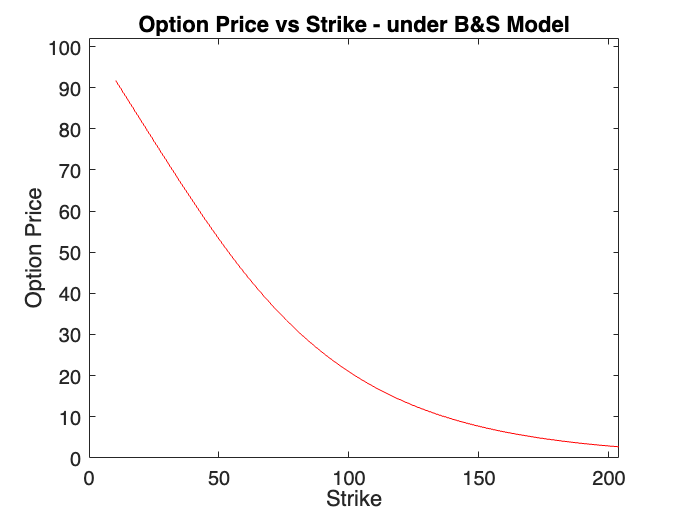

% Trapezoïdal quadrature formula :
w = ones(1, N);
w(1) = 0.5;
w(end) = 0.5;

% Argument inside FFT_MATLAB (or IFFT_PROBABILISTS) :
x_BS = w .* eta .* Z_k_BS .* exp(1i * pi * (0:N-1));
x_KOU = w .* eta .* Z_k_KOU .* exp(1i * pi * (0:N-1));
x_MERTON = w .* eta .* Z_k_MERTON .* exp(1i * pi * (0:N-1));


% FFT formula for z_T(k_l): 
z_k_BS = real(fft(x_BS) / pi); 
z_k_KOU = real(fft(x_KOU) / pi); 
z_k_MERTON = real(fft(x_MERTON) / pi); 

**Warning: ***we use fft() funtion because MATLAB's FFT is implemented with a "-" in the exponential, whereas probabilists use the IFT  with a "-" in the exponential. So here we perform FFT in Matlab's POV, but it corresponds to the IFT in mathematician's POV.*

**Warning: ***We know theoretically that the price should be a real number, but due to numerical approximation we must use the real() function to cap the imaginary part to, indeed, zero.*

**3) Retrieve the call option price **starting from $z_T(k)$ :


$$c(k) = z_T(k) + \left(1-e^{k-rT}\right)^+$$


C_BS = S0 * (z_k_BS + max(1 - exp(k - r * T), 0)); % Option prices array.
C_KOU = S0 * (z_k_KOU + max(1 - exp(k - r * T), 0));
C_MERTON = S0 * (z_k_MERTON + max(1 - exp(k - r * T), 0));

We can **process the output** by retrieving the real strikes $K$, removing very small strikes and very large strikes :

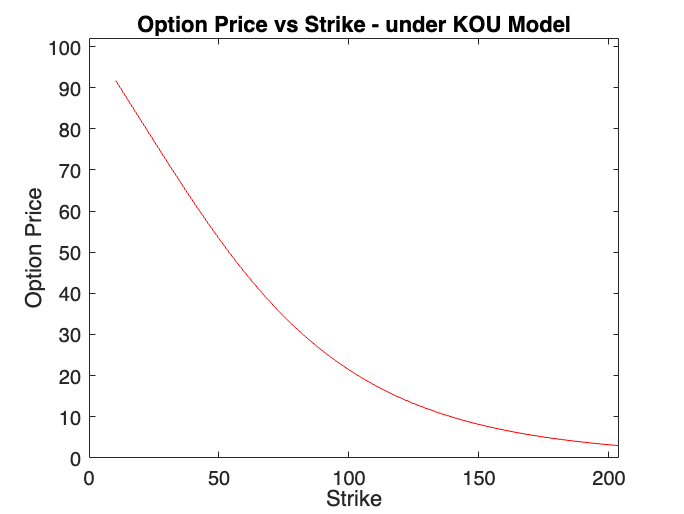

% Get strikes from log-strikes:

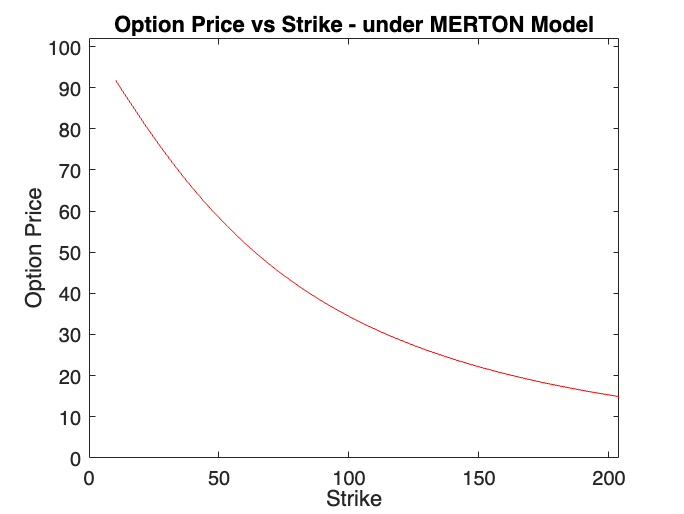

K = S0 * exp(k);

% Filter strikes:
index = find(K > 0.1 * S0 & K < 3 * S0);
K = K(index);

% Filter prices:
C_BS = C_BS(index);

C_KOU = C_KOU(index);
C_MERTON = C_MERTON(index);

Price_BS =    30.9938   25.5337   20.9583   17.1626


Finally we can **plot** everything:

- B&S model:

figure

Price_KOU =    31.3565   25.9582   21.4253   17.6532


plot(K, C_BS, 'r');

Price_MERTON =    42.0723   37.9854   34.4234   31.3088


hold on
axis([0 2*S0 0 S0]);
title('Option Price vs Strike - under B&S Model');
ylabel('Option Price');
xlabel('Strike');

- KOU model:

figure
plot(K, C_KOU, 'r');
hold on
axis([0 2*S0 0 S0]);
title('Option Price vs Strike - under KOU Model');
ylabel('Option Price');
xlabel('Strike');

- MERTON model:

figure
plot(K, C_MERTON, 'r');
hold on
axis([0 2*S0 0 S0]);
title('Option Price vs Strike - under MERTON Model');
ylabel('Option Price');
xlabel('Strike');

And we can **interpolate to get the prices for a very specific set of strikes**:

Price_BS = interp1(K, C_BS, Strike, 'spline')
Price_KOU = interp1(K, C_KOU, Strike, 'spline')
Price_MERTON = interp1(K, C_MERTON, Strike, 'spline')

## Calibration to the market prices :

Obviously, if there is a **closed formula **there is no problem : we calibrate using the formula : e.g when we inverse the B&S formula to find the volatility $\sigma
$. But i**n the general Lévy framework, we don't have a closed formula**. So** Carr-Madan algorithm is a great choice to perform the calibration of the model based on the market prices** : it is **fast** and **accurate**.

### A) Calibration of the Kou Model:

Let's use CM algorithm to find the best parameters 'params' which represent $(\sigma, \lambda, p, \lambda_+, \lambda_-)
$ that best fits market prices, under Kou Model.

**1) The data:**

Maturity = 4/12; % Maturity of 4 months 
Data = [25.30	200 % Prices, Strikes
        10.00	225
        18.20	210
        41.85	180
        15.20	215
        7.85	230
        12.36	220
        46.05	175
        70.70	150
        50.85	170
        60.40	160
        29.40	195];
Data1 = [Data(:,2), Maturity * ones(size(Data(:,2))), Data(:,1)];
% Data1 is in the form : [Strike, Time to Maturity, Market Price].

Maturity = 4/252; % Maturity of 4 (trading) days


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


params =     0.2115    0.6554    0.0000   50.0000    6.7451


error = 1.0934

Data = [0.24	230
        9.25	210

Elapsed time is 3.228849 seconds.


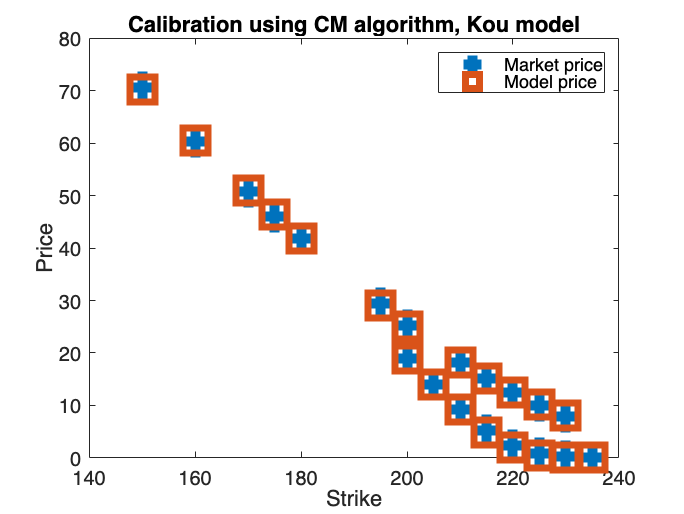

        2.26	220
        0.76	225
        19.03	200
        5.20	215
        14.00	205
        0.10	235];
Data = [Data(:,2), Maturity * ones(size(Data(:,2))), Data(:,1)];
% Data is in the form : [Strike, Time to Maturity, Market Price].

Data = [Data1; Data]; % We merge the two datasets (with two different 
% maturities).

**2) Optimisation:**

- We want to compute the parameters 'params' which represent $(\sigma, \lambda, p, \lambda_+, \lambda_-)$ and which minimize the distance between market prices and prices computed by the Kou model. The function that computes the model prices under Kou is 'fun.m' : it does so via CM algorithm.

% Parameters :
r = 0.02; spot = 218.75;

% Optimisation :
x0 = [0.5, 5, 0.8, 15, 15]; % Initial guess
LB = [0.1, 0, 0, 1,1];      % Lower bound
UB = [0.8, 20, 1, 50, 50];  % Upper bound

tic

[params, error] = lsqnonlin(@(params) ...
        fun(params, spot, Data(:,1), r, Data(:,2), Data(:,3)), ...
        x0, LB, UB)


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


params =     0.2140    0.2933   -0.2579    0.1471


error = 1.1214


toc

Elapsed time is 2.320401 seconds.


**3) Plot:**

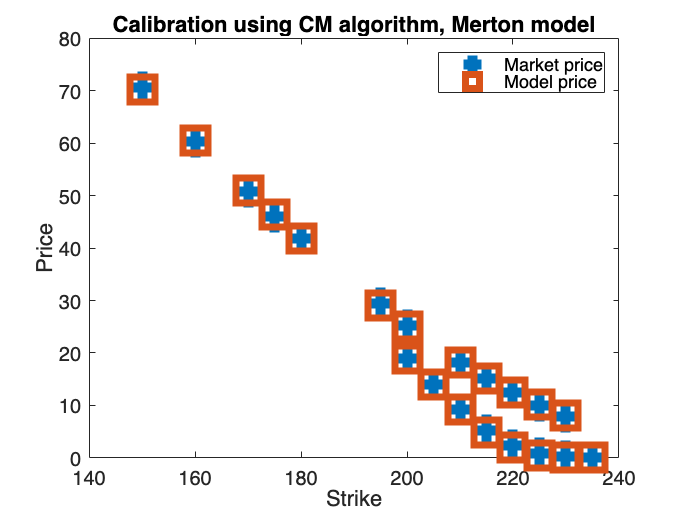

figure
plot(Data(:,1), Data(:,3), '+', 'markersize', 16, 'linewidth', 5); 
hold on
% Compute and plot the calibrated prices (so with the calibrated sigma) :
Price = fun(params, spot, Data(:,1), r, Data(:,2), 0);
plot(Data(:,1), Price, 's', 'markersize', 16, 'linewidth', 5); 
legend('Market price', 'Model price')
xlabel("Strike")
ylabel("Price")
title("Calibration using CM algorithm, Kou model")

### B) Calibration of the Merton model:

**1) The data:**

same as before.

**2) Optimisation:**

% Parameters :
r = 0.02; spot = 218.75;

% Optimisation :
x0 = [0.5, 5, 0.8, 0.5];   % Initial guess
LB = [0,  0, -2, 0];       % Lower bound
UB = [2,  20, 2, 20];      % Upper bound

tic

[params, error] = lsqnonlin(@(params) ...
        fun_MERTON(params, spot, Data(:,1), r, Data(:,2), Data(:,3)), ...
        x0, LB, UB)


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


params =     0.2517    5.0000    0.8000   15.0000   15.0000


error = 4.8569


toc

Elapsed time is 0.416198 seconds.


**3) Plot:**

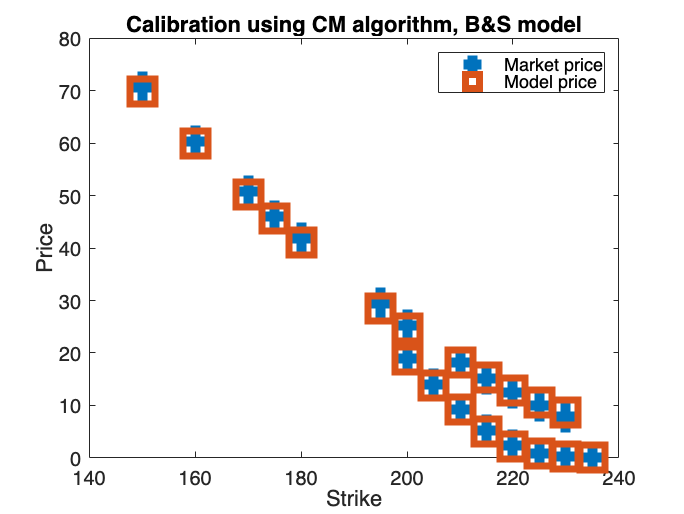

figure
plot(Data(:,1), Data(:,3), '+', 'markersize', 16, 'linewidth', 5); 
hold on
% Compute and plot the calibrated prices (so with the calibrated sigma) :
Price = fun_MERTON(params, spot, Data(:,1), r, Data(:,2), 0);
plot(Data(:,1), Price, 's', 'markersize', 16, 'linewidth', 5); 
legend('Market price', 'Model price')
xlabel("Strike")
ylabel("Price")
title("Calibration using CM algorithm, Merton model")

### C) Calibration of the B&S model:

**1) The data:**

same as before.

**2) Optimisation:**

- **Warning: **look only at the first parameter in 'params', since it is the only one for B&S model. The others are for models such as Kou or Merton (cf before).

% Parameters :
r = 0.02; spot = 218.75;

% Optimisation :
x0 = [0.5, 5, 0.8, 15, 15]; % Initial guess
LB = [0.1, 0, 0, 1,1];      % Lower bound
UB = [0.8, 20, 1, 50, 50];  % Upper bound

tic

[params, error] = lsqnonlin(@(params) ...
        fun_CM_BS(params, spot, Data(:,1), r, Data(:,2), Data(:,3)), ...
        x0, LB, UB)

toc

**3) Plot:**

figure
plot(Data(:,1), Data(:,3), '+', 'markersize', 16, 'linewidth', 5); 
hold on
% Compute and plot the calibrated prices (so with the calibrated sigma) :
Price = fun_CM_BS(params, spot, Data(:,1), r, Data(:,2), 0);
plot(Data(:,1), Price, 's', 'markersize', 16, 'linewidth', 5); 
legend('Market price', 'Model price')
xlabel("Strike")
ylabel("Price")
title("Calibration using CM algorithm, B&S model")

*We can see that the B&S calibration is the worst between the three calibrations we performed. It seems normal since it only has one parameter (sigma).*